# Data preparation

## Load the training data

We load the original dataset in training_dataset/', and create two cell arrays:

- dataTables: A cellarray of 3600 elements, each element is a dataTable, contains all the available features.

- y: A cellarray of 3600 elements, each element is the label (str).

clear; clc; close all;

% Set random seed for reproduction purpose.
rng(10);

doTraining = true;
mdlName = 'mdlTrajCmdTrajResidual.mat';

% Define the path to check for 'conc_dataset.mat'
pathLoggedTrainingData = 'training_dataset/training_dataset.mat';
pathTrainingData = 'training_dataset/';

% Define a DataLoader instance.
% Define the length of simulation and the corresponding sequence length.
lenSeries = 1000; % Sequence length.
simulationTime = 10; % The time that this sequence corresponds to.
dataLoader = DataLoader(lenSeries, simulationTime);
dataLoader.pathTrainingDataset = pathTrainingData;
dataLoader.pathLoggedTrainingData = pathLoggedTrainingData;
[dataTables, y] = dataLoader.loadTrainingData();

Loaded data from training_dataset/training_dataset.mat


We can print an example of all the features.

dataTables{1}

ans = 1000×12 table
    Timestamps    Motor1Cmd    Motor2Cmd     Motor3Cmd      Motor4Cmd     Motor5Cmd    DesiredTrajectory-x    DesiredTrajectory-y    DesiredTrajectory-z    RealizedTrajectory-x    RealizedTrajectory-y    RealizedTrajectory-z
    __________    _________    _________    ___________    ___________    _________    ___________________    ___________________    ___________________    ____________________    ____________________    ____________________

          0              0             0              0              0        0             3.7297e-17            -6.9389

## Training and validation set creation

We randomly split a dataset and train a LSTM.

% Shuffle the dataset using the cvpartition function
training_ratio = .9;
n_dataset = numel(dataTables);
training_size = floor(training_ratio*n_dataset);
cvObj = cvpartition(y, 'HoldOut', training_size);
idx = cvObj.test;

% Split into training and test data based on training size specified
X_train = dataTables(idx');
X_test = dataTables(~idx');
y_train = categorical(y(idx'));
y_test = categorical(y(~idx'));

We can show the distribution of classes in the training and testing dataset, to make sure the seperation is fair.

summary(y_train);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     360          360                             360                360                             360                360                             360                360                             360           


summary(y_test);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     40           40                              40                 40                              40                 40                              40                 40                              40            


# Pre-processing and feature engineering

In this section, we preprocess the data and augument the dataset by adding some new features from feature engineering.

% Add an additional feature of the residual.
X_train = dataLoader.extractFeaturesTrajCmdTrajResidual(X_train);
X_test = dataLoader.extractFeaturesTrajCmdTrajResidual(X_test);

## Normalize Training Features

Networks will often train better when normalized. Calculate the mean and standard deviation and normalize each element of the training feature set. 

X_train = normalize_features(X_train);
X_test = normalize_features(X_test);

# Training and evaluating the model

Use an LSTM network. An LSTM layer learns long-term dependencies between time steps of time series or sequence data. The first lstmlayer will have 100 hidden units and output the sequence data. Then a dropout layer will be used to reduce probability of overfitting. The second lstmlayer will output just the last step of the time sequence.

layers = [ ...
    sequenceInputLayer(size(X_train{1},1))
    lstmLayer(100,"OutputMode","sequence")
    dropoutLayer(0.1)
    lstmLayer(100,"OutputMode","last")
    fullyConnectedLayer(numel(categories(y_train)))
    softmaxLayer
    classificationLayer];

## Define Network Hyperparameters

miniBatchSize = 32;
validationFrequency = floor(numel(X_train)/miniBatchSize);
options = trainingOptions("adam", ...
    "MaxEpochs",30, ...
    "MiniBatchSize",miniBatchSize, ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "Shuffle","every-epoch", ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",20,...
    'ValidationData',{X_test, y_test}, ...
    'ValidationFrequency',validationFrequency);

## Train The Network

This network takes about 100 seconds to train on an NVIDIA RTX 2080 GPU.

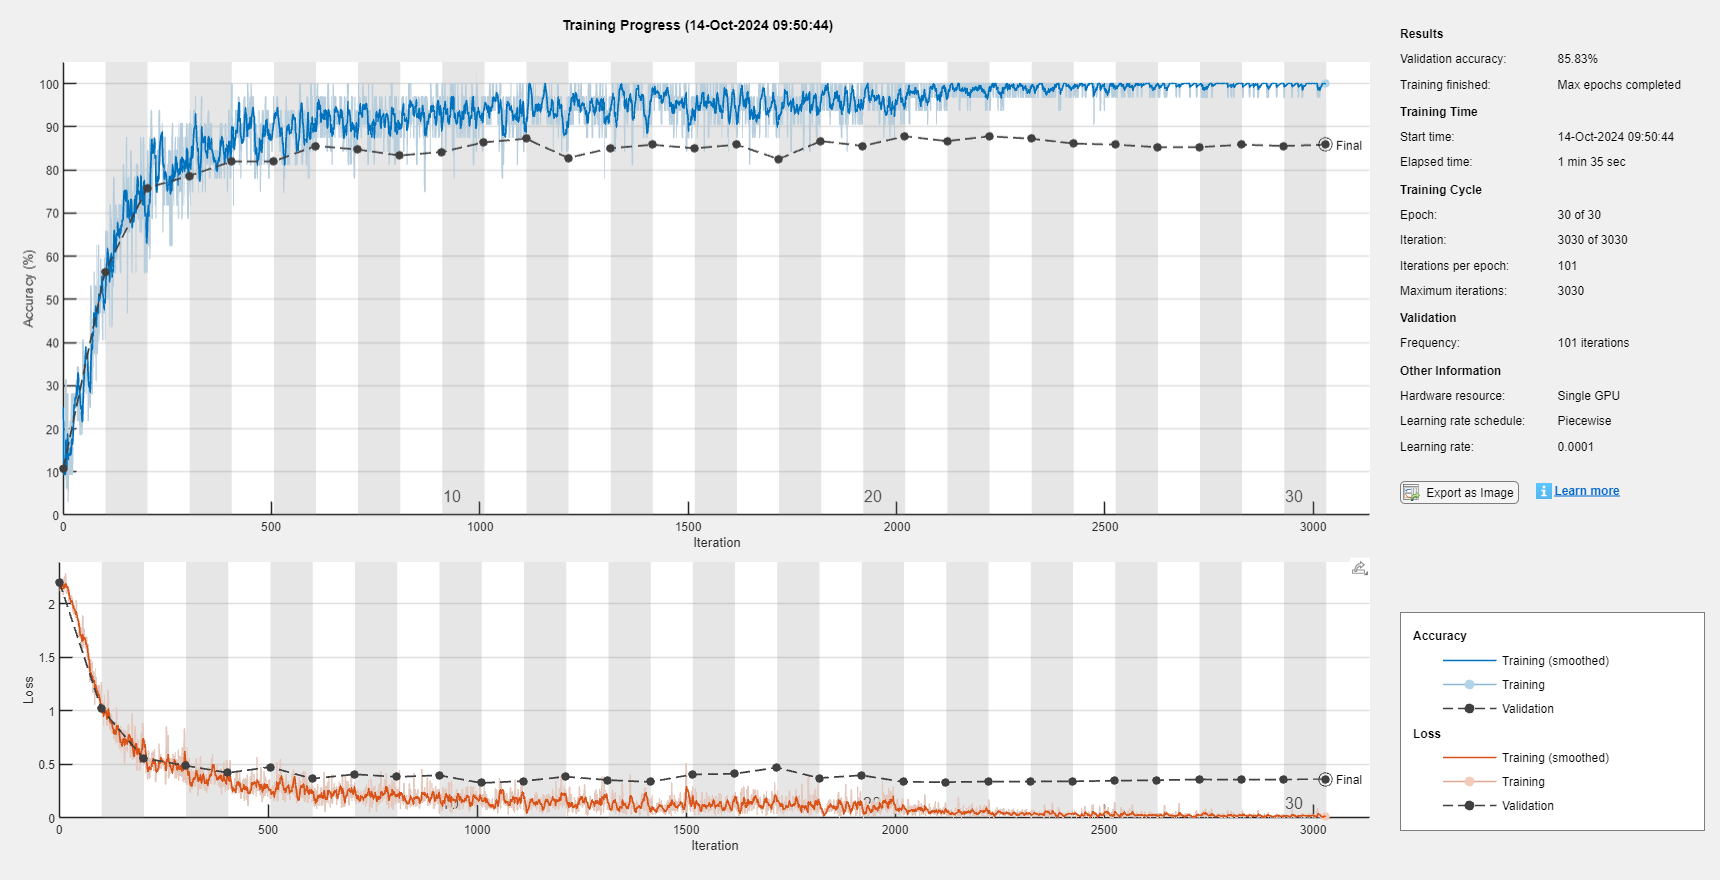

if doTraining
    diagnosisNet = trainNetwork(X_train, y_train, layers, options);
    save(mdlName, 'diagnosisNet');
else
    load(mdlName, 'diagnosisNet');
end

## Test The Network

Now that the network has been trained, we can test it on the validation data. 

y_pred = classify(diagnosisNet, X_test);

View the confusion chart for the test results:

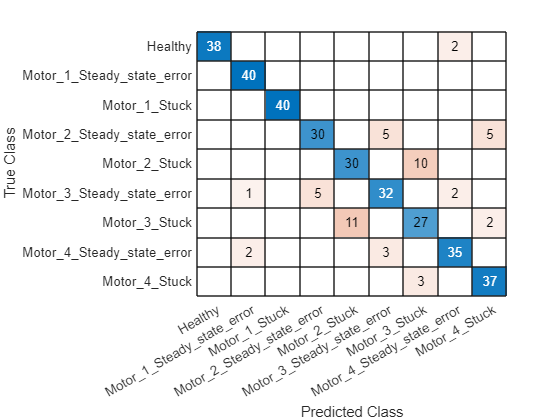

cm = confusionchart(y_test', y_pred);

View the overall accuracy percentage of the validation and test results:

[accuracy, precision, recall, f1Score] = dataLoader.evalPerf(y_test, y_pred);
% Display the results
fprintf('Overall Accuracy: %.2f%%\n', accuracy * 100);

Overall Accuracy: 85.83%


class_names = categories(y_test);
for i = 1:numel(class_names)
    fprintf('Class %d (%s): Precision = %.2f, Recall = %.2f, F1 Score = %.2f\n', i, class_names{i}, precision(i), recall(i), f1Score(i));
end

Class 1 (Healthy): Precision = 1.00, Recall = 0.95, F1 Score = 0.97
Class 2 (Motor_1_Steady_state_error): Precision = 0.93, Recall = 1.00, F1 Score = 0.96
Class 3 (Motor_1_Stuck): Precision = 1.00, Recall = 1.00, F1 Score = 1.00
Class 4 (Motor_2_Steady_state_error): Precision = 0.86, Recall = 0.75, F1 Score = 0.80
Class 5 (Motor_2_Stuck): Precision = 0.73, Recall = 0.75, F1 Score = 0.74
Class 6 (Motor_3_Steady_state_error): Precision = 0.80, Recall = 0.80, F1 Score = 0.80
Class 7 (Motor_3_Stuck): Precision = 0.68, Recall = 0.68, F1 Score = 0.68
Class 8 (Motor_4_Steady_state_error): Precision = 0.90, Recall = 0.88, F1 Score = 0.89
Class 9 (Motor_4_Stuck): Precision = 0.84, Recall = 0.93, F1 Score = 0.88


# Supporting functions

function X = normalize_features(X)
    % This function normalizes the features.
    % Input: X is an cell array of 1*n_data, whose elements are matrixs of
    % (n_seq, n_features).

    % Concatenate all the features. Creat a matrix of (n_seq*n_data,
    % n_features).
    allFeatures = cat(1, X{:});

    % Do the normalization.
    M = mean(allFeatures);
    S = std(allFeatures);
    
    for index = 1:numel(X)
       X{index} =  ((X{index} - M)./S);
    end
end